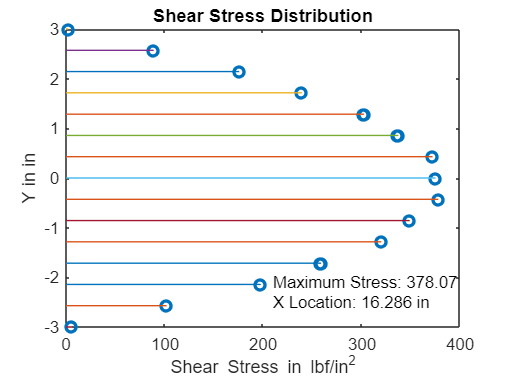

shear = table2array(readtable("shear_stress","Range","A2:E6282"));
[r,c]=size(shear);
profile_s=zeros(r,2);
for i=1:r
    if(shear(i,2)==16.286)
        profile_s(i,1)=shear(i,3);
        profile_s(i,2)=shear(i,5);
    else
        profile_s(i,1)=NaN;
        profile_s(i,2)=NaN;
    end
end
[max_s,k]=max(profile_s(:,2));
plot(profile_s(:,2),profile_s(:,1),'o',"LineWidth",2);
for i=1:r
    if(~isnan(profile_s(i,1)))
        hold on
        plot([0 profile_s(i,2)], [profile_s(i,1) profile_s(i,1)])
    end
end
txt3 = ['Maximum Stress: ',num2str(max_s)];
text ( 210, -2.1, txt3);
txt4 = 'X Location: 16.286 in';
text ( 210, -2.5, txt4);
xlabel("Shear Stress in lbf/in^2");
ylabel("Y in in");
title("Shear Stress Distribution")
hold off;

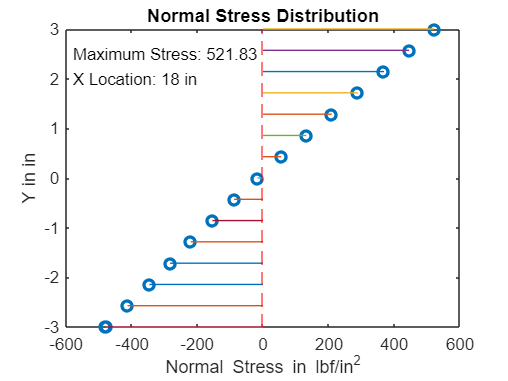

normal = table2array(readtable("normal_stress","Range","A2:E6282"));
profile_n=zeros(r,2);
for i=1:r
    if(normal(i,2)==18)
        profile_n(i,1)=normal(i,3);
        profile_n(i,2)=normal(i,5);
    else
        profile_n(i,1)=NaN;
        profile_n(i,2)=NaN;
    end
end
[max_n,j]=max(profile_n(:,2));
plot(profile_n(:,2),profile_n(:,1),'o',"LineWidth",2);
xline(0,'--r');
for i=1:r
    if(~isnan(profile_n(i,1)))
        hold on
        plot([0 profile_n(i,2)], [profile_n(i,1) profile_n(i,1) ])
    end
end
txt1 = ['Maximum Stress: ',num2str(max_n)];
text ( -580, 2.5, txt1);
txt2 = 'X Location: 18 in';
text ( -580, 2, txt2);
xlabel("Normal Stress in lbf/in^2");
ylabel("Y in in");
title("Normal Stress Distribution")
hold off;